# NeuroTech 2021 ANOVA Exploration

## Example Walthrough of using ANOVA on a data set

**Sam Coleman**

Data set source: [https://college.cengage.com/mathematics/brase/understandable_statistics/7e/students/datasets/owan/frames/owan04.html](https://college.cengage.com/mathematics/brase/understandable_statistics/7e/students/datasets/owan/frames/owan04.html)

**The following data represent business startup costs (thousands of dollars) for shops.**

 X1 = startup costs for pizza 

 X2 = startup costs for baker/donuts

 X3 = startup costs for shoe stores

 X4 = startup costs for gift shops

 X5 = startup costs for pet stores

Null Hypothesis ($H_0$): The startup costs for all business are the same

data = readtable("anovaData.csv") %import data

data = 16×5 table
    X1     X2     X3     X4     X5 
    ___    ___    ___    ___    ___

     80    150     48    100     25
    125     40     35     96     80
     35    120     95     35     30
     58     75     45     99     35
    110    160     75     75     30
    140     60    115    150     28
     97     45     42     45     20
     50    100     78    100     75
     65     86     65    120     48
     79     87    125     50     20
     35     90    NaN    NaN     50
     85    NaN    NaN    NaN     75
    120    NaN    NaN    NaN     55
    NaN    NaN    NaN    NaN     60
    NaN    NaN    NaN    NaN     85
    NaN    NaN    NaN    NaN    110


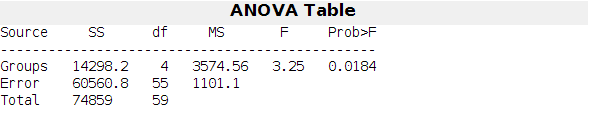

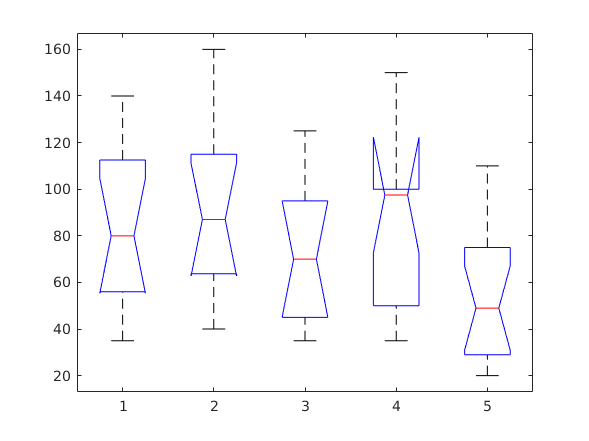

p = 0.0184


x_vals = [data.X1, data.X2, data.X3, data.X4, data.X5]; %put data into matrix 
p = anova1(x_vals) %use MATLAB ANOVA function

We see the p value is .0184 which is 1.8%. Since this is under 5%, we will reject the null hypothesis.